syms s  Kp Ki l g tau k x

tau_value = 0.103;
k_value = 2.439;
l_value = 0.4822;
g_value = 9.8;
%kp_value = 1.4;
%ki_value = 4.83;

Ms = (k/tau) / (s+(1/tau));
Hs = (-s/l) / (s^2-(g/l));
Ks = Kp + (Ki/s);

transfer_function = ((simplify((1)/(1 - (Hs*Ks*Ms)))));

hello = subs(transfer_function, l, l_value);
hello = subs(hello, k, k_value);
hello = subs(hello, g, g_value);
hello = subs(hello, tau, tau_value);
Ha = hello;



RANGE_VALS = 200;

for i = 1:RANGE_VALS
    val_kp = 1+i*0.01;
    for k = 1:RANGE_VALS
        val_ki = 3+k*0.01;
        Ha = subs(hello, Kp, val_kp);
        Ha = subs(Ha, Ki, val_ki);
        [N, D] = numden(Ha);
        transfer_matlab_form = tf(sym2poly(N), sym2poly(D));
        P = pole(transfer_matlab_form);
        one_real = P(0==imag(P));
        imaginary_vals = P-real(P);
        % check that all are stable
        all_are_stable = (mean(real(P)<=0)==1);
        % check that imaginary values are ~4.5
        imag_correct = sum(round(10.*imaginary_vals)==45i);
        if all_are_stable && imag_correct
            val_kp
            val_ki
            P
            %figure()
            %pzplot(transfer_matlab_form)
        end
    end
end

val_kp = 1.3000

val_ki = 4.0200

P =   -4.8533 + 4.4655i
  -4.8533 - 4.4655i
  -0.0022 + 0.0000i


val_kp = 1.3000

val_ki = 4.0300

P =   -4.8476 + 4.4593i
  -4.8476 - 4.4593i
  -0.0135 + 0.0000i


val_kp = 1.3000

val_ki = 4.0400

P =   -4.8419 + 4.4532i
  -4.8419 - 4.4532i
  -0.0249 + 0.0000i


val_kp = 1.3100

val_ki = 4.0200

P =   -4.8533 + 4.5201i
  -4.8533 - 4.5201i
  -0.0022 + 0.0000i


val_kp = 1.3100

val_ki = 4.0300

P =   -4.8477 + 4.5141i
  -4.8477 - 4.5141i
  -0.0134 + 0.0000i


val_kp = 1.3100

val_ki = 4.0400

P =   -4.8420 + 4.5081i
  -4.8420 - 4.5081i
  -0.0246 + 0.0000i


val_kp = 1.3100

val_ki = 4.0500

P =   -4.8364 + 4.5021i
  -4.8364 - 4.5021i
  -0.0359 + 0.0000i


val_kp = 1.3100

val_ki = 4.0600

P =   -4.8307 + 4.4960i
  -4.8307 - 4.4960i
  -0.0473 + 0.0000i


val_kp = 1.3100

val_ki = 4.0700

P =   -4.8250 + 4.4900i
  -4.8250 - 4.4900i
  -0.0587 + 0.0000i


val_kp = 1.3100

val_ki = 4.0800

P =   -4.8193 + 4.4839i
  -4.8193 - 4.4839i
  -0.0702 + 0.0000i


val_kp = 1.3100

val_ki = 4.0900

P =   -4.8135 + 4.4778i
  -4.8135 - 4.4778i
  -0.0818 + 0.0000i


val_kp = 1.3100

val_ki = 4.1000

P =   -4.8077 + 4.4717i
  -4.8077 - 4.4717i
  -0.0934 + 0.0000i


val_kp = 1.3100

val_ki = 4.1100

P =   -4.8019 + 4.4655i
  -4.8019 - 4.4655i
  -0.1050 + 0.0000i


val_kp = 1.3100

val_ki = 4.1200

P =   -4.7960 + 4.4594i
  -4.7960 - 4.4594i
  -0.1167 + 0.0000i


val_kp = 1.3100

val_ki = 4.1300

P =   -4.7901 + 4.4532i
  -4.7901 - 4.4532i
  -0.1285 + 0.0000i


val_kp = 1.3200

val_ki = 4.0700

P =   -4.8253 + 4.5447i
  -4.8253 - 4.5447i
  -0.0581 + 0.0000i


val_kp = 1.3200

val_ki = 4.0800

P =   -4.8197 + 4.5387i
  -4.8197 - 4.5387i
  -0.0694 + 0.0000i


val_kp = 1.3200

val_ki = 4.0900

P =   -4.8140 + 4.5328i
  -4.8140 - 4.5328i
  -0.0808 + 0.0000i


val_kp = 1.3200

val_ki = 4.1000

P =   -4.8082 + 4.5268i
  -4.8082 - 4.5268i
  -0.0923 + 0.0000i


val_kp = 1.3200

val_ki = 4.1100

P =   -4.8025 + 4.5208i
  -4.8025 - 4.5208i
  -0.1038 + 0.0000i


val_kp = 1.3200

val_ki = 4.1200

P =   -4.7967 + 4.5148i
  -4.7967 - 4.5148i
  -0.1154 + 0.0000i


val_kp = 1.3200

val_ki = 4.1300

P =   -4.7909 + 4.5088i
  -4.7909 - 4.5088i
  -0.1270 + 0.0000i


val_kp = 1.3200

val_ki = 4.1400

P =   -4.7850 + 4.5027i
  -4.7850 - 4.5027i
  -0.1387 + 0.0000i


val_kp = 1.3200

val_ki = 4.1500

P =   -4.7791 + 4.4966i
  -4.7791 - 4.4966i
  -0.1505 + 0.0000i


val_kp = 1.3200

val_ki = 4.1600

P =   -4.7732 + 4.4906i
  -4.7732 - 4.4906i
  -0.1623 + 0.0000i


val_kp = 1.3200

val_ki = 4.1700

P =   -4.7673 + 4.4845i
  -4.7673 - 4.4845i
  -0.1742 + 0.0000i


val_kp = 1.3200

val_ki = 4.1800

P =   -4.7613 + 4.4784i
  -4.7613 - 4.4784i
  -0.1862 + 0.0000i


val_kp = 1.3200

val_ki = 4.1900

P =   -4.7553 + 4.4722i
  -4.7553 - 4.4722i
  -0.1982 + 0.0000i


val_kp = 1.3200

val_ki = 4.2000

P =   -4.7492 + 4.4661i
  -4.7492 - 4.4661i
  -0.2102 + 0.0000i


val_kp = 1.3200

val_ki = 4.2100

P =   -4.7432 + 4.4599i
  -4.7432 - 4.4599i
  -0.2224 + 0.0000i


val_kp = 1.3200

val_ki = 4.2200

P =   -4.7371 + 4.4537i
  -4.7371 - 4.4537i
  -0.2346 + 0.0000i


val_kp = 1.3300

val_ki = 4.1600

P =   -4.7742 + 4.5459i
  -4.7742 - 4.5459i
  -0.1604 + 0.0000i


val_kp = 1.3300

val_ki = 4.1700

P =   -4.7683 + 4.5399i
  -4.7683 - 4.5399i
  -0.1722 + 0.0000i


val_kp = 1.3300

val_ki = 4.1800

P =   -4.7624 + 4.5340i
  -4.7624 - 4.5340i
  -0.1839 + 0.0000i


val_kp = 1.3300

val_ki = 4.1900

P =   -4.7565 + 4.5280i
  -4.7565 - 4.5280i
  -0.1958 + 0.0000i


val_kp = 1.3300

val_ki = 4.2000

P =   -4.7505 + 4.5220i
  -4.7505 - 4.5220i
  -0.2077 + 0.0000i


val_kp = 1.3300

val_ki = 4.2100

P =   -4.7445 + 4.5160i
  -4.7445 - 4.5160i
  -0.2197 + 0.0000i


val_kp = 1.3300

val_ki = 4.2200

P =   -4.7385 + 4.5100i
  -4.7385 - 4.5100i
  -0.2318 + 0.0000i


val_kp = 1.3300

val_ki = 4.2300

P =   -4.7324 + 4.5039i
  -4.7324 - 4.5039i
  -0.2439 + 0.0000i


val_kp = 1.3300

val_ki = 4.2400

P =   -4.7263 + 4.4979i
  -4.7263 - 4.4979i
  -0.2561 + 0.0000i


val_kp = 1.3300

val_ki = 4.2500

P =   -4.7202 + 4.4918i
  -4.7202 - 4.4918i
  -0.2683 + 0.0000i


val_kp = 1.3300

val_ki = 4.2600

P =   -4.7141 + 4.4857i
  -4.7141 - 4.4857i
  -0.2806 + 0.0000i


val_kp = 1.3300

val_ki = 4.2700

P =   -4.7079 + 4.4796i
  -4.7079 - 4.4796i
  -0.2930 + 0.0000i


val_kp = 1.3300

val_ki = 4.2800

P =   -4.7017 + 4.4735i
  -4.7017 - 4.4735i
  -0.3054 + 0.0000i


val_kp = 1.3300

val_ki = 4.2900

P =   -4.6954 + 4.4673i
  -4.6954 - 4.4673i
  -0.3180 + 0.0000i


val_kp = 1.3300

val_ki = 4.3000

P =   -4.6891 + 4.4611i
  -4.6891 - 4.4611i
  -0.3305 + 0.0000i


val_kp = 1.3300

val_ki = 4.3100

P =   -4.6828 + 4.4550i
  -4.6828 - 4.4550i
  -0.3432 + 0.0000i


val_kp = 1.3400

val_ki = 4.2500

P =   -4.7218 + 4.5477i
  -4.7218 - 4.5477i
  -0.2650 + 0.0000i


val_kp = 1.3400

val_ki = 4.2600

P =   -4.7158 + 4.5418i
  -4.7158 - 4.5418i
  -0.2772 + 0.0000i


val_kp = 1.3400

val_ki = 4.2700

P =   -4.7097 + 4.5358i
  -4.7097 - 4.5358i
  -0.2894 + 0.0000i


val_kp = 1.3400

val_ki = 4.2800

P = 3×1
  -4.7035 + 4.5298i
  -4.7035 - 4.5298i
  -0.3017 + 0.0000i


val_kp = 1.3400

val_ki = 4.2900

P = 3×1
  -4.6974 + 4.5238i
  -4.6974 - 4.5238i
  -0.3140 + 0.0000i


val_kp = 1.3400

val_ki = 4.3000

P = 3×1
  -4.6912 + 4.5178i
  -4.6912 - 4.5178i
  -0.3264 + 0.0000i


val_kp = 1.3400

val_ki = 4.3100

P = 3×1
  -4.6849 + 4.5118i
  -4.6849 - 4.5118i
  -0.3389 + 0.0000i


val_kp = 1.3400

val_ki = 4.3200

P = 3×1
  -4.6786 + 4.5058i
  -4.6786 - 4.5058i
  -0.3515 + 0.0000i


val_kp = 1.3400

val_ki = 4.3300

P = 3×1
  -4.6723 + 4.4997i
  -4.6723 - 4.4997i
  -0.3641 + 0.0000i


val_kp = 1.3400

val_ki = 4.3400

P = 3×1
  -4.6660 + 4.4937i
  -4.6660 - 4.4937i
  -0.3768 + 0.0000i


val_kp = 1.3400

val_ki = 4.3500

P = 3×1
  -4.6596 + 4.4876i
  -4.6596 - 4.4876i
  -0.3895 + 0.0000i


val_kp = 1.3400

val_ki = 4.3600

P = 3×1
  -4.6532 + 4.4815i
  -4.6532 - 4.4815i
  -0.4024 + 0.0000i


val_kp = 1.3400

val_ki = 4.3700

P = 3×1
  -4.6467 + 4.4754i
  -4.6467 - 4.4754i
  -0.4153 + 0.0000i


val_kp = 1.3400

val_ki = 4.3800

P = 3×1
  -4.6402 + 4.4693i
  -4.6402 - 4.4693i
  -0.4282 + 0.0000i


val_kp = 1.3400

val_ki = 4.3900

P = 3×1
  -4.6337 + 4.4631i
  -4.6337 - 4.4631i
  -0.4413 + 0.0000i


val_kp = 1.3400

val_ki = 4.4000

P = 3×1
  -4.6271 + 4.4570i
  -4.6271 - 4.4570i
  -0.4544 + 0.0000i


val_kp = 1.3400

val_ki = 4.4100

P = 3×1
  -4.6205 + 4.4508i
  -4.6205 - 4.4508i
  -0.4677 + 0.0000i


val_kp = 1.3500

val_ki = 4.3500

P = 3×1
  -4.6621 + 4.5443i
  -4.6621 - 4.5443i
  -0.3846 + 0.0000i


val_kp = 1.3500

val_ki = 4.3600

P = 3×1
  -4.6557 + 4.5383i
  -4.6557 - 4.5383i
  -0.3973 + 0.0000i


val_kp = 1.3500

val_ki = 4.3700

P = 3×1
  -4.6494 + 4.5324i
  -4.6494 - 4.5324i
  -0.4100 + 0.0000i


val_kp = 1.3500

val_ki = 4.3800

P = 3×1
  -4.6430 + 4.5264i
  -4.6430 - 4.5264i
  -0.4228 + 0.0000i


val_kp = 1.3500

val_ki = 4.3900

P = 3×1
  -4.6366 + 4.5204i
  -4.6366 - 4.5204i
  -0.4356 + 0.0000i


val_kp = 1.3500

val_ki = 4.4000

P = 3×1
  -4.6301 + 4.5144i
  -4.6301 - 4.5144i
  -0.4485 + 0.0000i


val_kp = 1.3500

val_ki = 4.4100

P = 3×1
  -4.6236 + 4.5084i
  -4.6236 - 4.5084i
  -0.4615 + 0.0000i


val_kp = 1.3500

val_ki = 4.4200

P = 3×1
  -4.6171 + 4.5024i
  -4.6171 - 4.5024i
  -0.4746 + 0.0000i


val_kp = 1.3500

val_ki = 4.4300

P = 3×1
  -4.6105 + 4.4964i
  -4.6105 - 4.4964i
  -0.4878 + 0.0000i


val_kp = 1.3500

val_ki = 4.4400

P = 3×1
  -4.6039 + 4.4903i
  -4.6039 - 4.4903i
  -0.5010 + 0.0000i


val_kp = 1.3500

val_ki = 4.4500

P = 3×1
  -4.5972 + 4.4842i
  -4.5972 - 4.4842i
  -0.5143 + 0.0000i


val_kp = 1.3500

val_ki = 4.4600

P = 3×1
  -4.5905 + 4.4781i
  -4.5905 - 4.4781i
  -0.5277 + 0.0000i


val_kp = 1.3500

val_ki = 4.4700

P = 3×1
  -4.5838 + 4.4720i
  -4.5838 - 4.4720i
  -0.5412 + 0.0000i


val_kp = 1.3500

val_ki = 4.4800

P = 3×1
  -4.5770 + 4.4659i
  -4.5770 - 4.4659i
  -0.5548 + 0.0000i


val_kp = 1.3500

val_ki = 4.4900

P = 3×1
  -4.5702 + 4.4598i
  -4.5702 - 4.4598i
  -0.5684 + 0.0000i


val_kp = 1.3500

val_ki = 4.5000

P = 3×1
  -4.5633 + 4.4537i
  -4.5633 - 4.4537i
  -0.5821 + 0.0000i


val_kp = 1.3600

val_ki = 4.4400

P = 3×1
  -4.6071 + 4.5476i
  -4.6071 - 4.5476i
  -0.4945 + 0.0000i


val_kp = 1.3600

val_ki = 4.4500

P = 3×1
  -4.6006 + 4.5417i
  -4.6006 - 4.5417i
  -0.5076 + 0.0000i


val_kp = 1.3600

val_ki = 4.4600

P = 3×1
  -4.5940 + 4.5358i
  -4.5940 - 4.5358i
  -0.5207 + 0.0000i


val_kp = 1.3600

val_ki = 4.4700

P = 3×1
  -4.5874 + 4.5298i
  -4.5874 - 4.5298i
  -0.5340 + 0.0000i


val_kp = 1.3600

val_ki = 4.4800

P = 3×1
  -4.5807 + 4.5239i
  -4.5807 - 4.5239i
  -0.5473 + 0.0000i


val_kp = 1.3600

val_ki = 4.4900

P = 3×1
  -4.5740 + 4.5179i
  -4.5740 - 4.5179i
  -0.5607 + 0.0000i


val_kp = 1.3600

val_ki = 4.5000

P = 3×1
  -4.5673 + 4.5119i
  -4.5673 - 4.5119i
  -0.5742 + 0.0000i


val_kp = 1.3600

val_ki = 4.5100

P = 3×1
  -4.5605 + 4.5059i
  -4.5605 - 4.5059i
  -0.5878 + 0.0000i


val_kp = 1.3600

val_ki = 4.5200

P = 3×1
  -4.5537 + 4.4999i
  -4.5537 - 4.4999i
  -0.6014 + 0.0000i


val_kp = 1.3600

val_ki = 4.5300

P = 3×1
  -4.5468 + 4.4939i
  -4.5468 - 4.4939i
  -0.6152 + 0.0000i


val_kp = 1.3600

val_ki = 4.5400

P = 3×1
  -4.5399 + 4.4879i
  -4.5399 - 4.4879i
  -0.6290 + 0.0000i


val_kp = 1.3600

val_ki = 4.5500

P = 3×1
  -4.5329 + 4.4818i
  -4.5329 - 4.4818i
  -0.6429 + 0.0000i


val_kp = 1.3600

val_ki = 4.5600

P = 3×1
  -4.5259 + 4.4758i
  -4.5259 - 4.4758i
  -0.6569 + 0.0000i


val_kp = 1.3600

val_ki = 4.5700

P = 3×1
  -4.5189 + 4.4697i
  -4.5189 - 4.4697i
  -0.6709 + 0.0000i


val_kp = 1.3600

val_ki = 4.5800

P = 3×1
  -4.5118 + 4.4636i
  -4.5118 - 4.4636i
  -0.6851 + 0.0000i


val_kp = 1.3600

val_ki = 4.5900

P = 3×1
  -4.5047 + 4.4575i
  -4.5047 - 4.4575i
  -0.6994 + 0.0000i


val_kp = 1.3600

val_ki = 4.6000

P = 3×1
  -4.4975 + 4.4514i
  -4.4975 - 4.4514i
  -0.7137 + 0.0000i


val_kp = 1.3700

val_ki = 4.5400

P = 3×1
  -4.5442 + 4.5460i
  -4.5442 - 4.5460i
  -0.6204 + 0.0000i


val_kp = 1.3700

val_ki = 4.5500

P = 3×1
  -4.5373 + 4.5401i
  -4.5373 - 4.5401i
  -0.6341 + 0.0000i


val_kp = 1.3700

val_ki = 4.5600

P = 3×1
  -4.5305 + 4.5342i
  -4.5305 - 4.5342i
  -0.6478 + 0.0000i


val_kp = 1.3700

val_ki = 4.5700

P = 3×1
  -4.5236 + 4.5283i
  -4.5236 - 4.5283i
  -0.6616 + 0.0000i


val_kp = 1.3700

val_ki = 4.5800

P = 3×1
  -4.5166 + 4.5224i
  -4.5166 - 4.5224i
  -0.6755 + 0.0000i


val_kp = 1.3700

val_ki = 4.5900

P = 3×1
  -4.5096 + 4.5164i
  -4.5096 - 4.5164i
  -0.6895 + 0.0000i


val_kp = 1.3700

val_ki = 4.6000

P = 3×1
  -4.5026 + 4.5105i
  -4.5026 - 4.5105i
  -0.7036 + 0.0000i


val_kp = 1.3700

val_ki = 4.6100

P = 3×1
  -4.4955 + 4.5045i
  -4.4955 - 4.5045i
  -0.7178 + 0.0000i


val_kp = 1.3700

val_ki = 4.6200

P = 3×1
  -4.4884 + 4.4986i
  -4.4884 - 4.4986i
  -0.7320 + 0.0000i


val_kp = 1.3700

val_ki = 4.6300

P = 3×1
  -4.4812 + 4.4926i
  -4.4812 - 4.4926i
  -0.7464 + 0.0000i


val_kp = 1.3700

val_ki = 4.6400

P = 3×1
  -4.4740 + 4.4866i
  -4.4740 - 4.4866i
  -0.7608 + 0.0000i


val_kp = 1.3700

val_ki = 4.6500

P = 3×1
  -4.4667 + 4.4806i
  -4.4667 - 4.4806i
  -0.7753 + 0.0000i


val_kp = 1.3700

val_ki = 4.6600

P = 3×1
  -4.4594 + 4.4746i
  -4.4594 - 4.4746i
  -0.7899 + 0.0000i


val_kp = 1.3700

val_ki = 4.6700

P = 3×1
  -4.4520 + 4.4686i
  -4.4520 - 4.4686i
  -0.8046 + 0.0000i


val_kp = 1.3700

val_ki = 4.6800

P = 3×1
  -4.4446 + 4.4626i
  -4.4446 - 4.4626i
  -0.8195 + 0.0000i


val_kp = 1.3700

val_ki = 4.6900

P = 3×1
  -4.4372 + 4.4565i
  -4.4372 - 4.4565i
  -0.8344 + 0.0000i


val_kp = 1.3700

val_ki = 4.7000

P = 3×1
  -4.4297 + 4.4505i
  -4.4297 - 4.4505i
  -0.8494 + 0.0000i


val_kp = 1.3800

val_ki = 4.6400

P = 3×1
  -4.4794 + 4.5454i
  -4.4794 - 4.5454i
  -0.7500 + 0.0000i


val_kp = 1.3800

val_ki = 4.6500

P = 3×1
  -4.4723 + 4.5396i
  -4.4723 - 4.5396i
  -0.7642 + 0.0000i


val_kp = 1.3800

val_ki = 4.6600

P = 3×1
  -4.4651 + 4.5338i
  -4.4651 - 4.5338i
  -0.7785 + 0.0000i


val_kp = 1.3800

val_ki = 4.6700

P = 3×1
  -4.4579 + 4.5279i
  -4.4579 - 4.5279i
  -0.7930 + 0.0000i


val_kp = 1.3800

val_ki = 4.6800

P = 3×1
  -4.4506 + 4.5221i
  -4.4506 - 4.5221i
  -0.8075 + 0.0000i


val_kp = 1.3800

val_ki = 4.6900

P = 3×1
  -4.4433 + 4.5162i
  -4.4433 - 4.5162i
  -0.8221 + 0.0000i


val_kp = 1.3800

val_ki = 4.7000

P = 3×1
  -4.4360 + 4.5103i
  -4.4360 - 4.5103i
  -0.8368 + 0.0000i


val_kp = 1.3800

val_ki = 4.7100

P = 3×1
  -4.4286 + 4.5044i
  -4.4286 - 4.5044i
  -0.8516 + 0.0000i


val_kp = 1.3800

val_ki = 4.7200

P = 3×1
  -4.4211 + 4.4985i
  -4.4211 - 4.4985i
  -0.8665 + 0.0000i


val_kp = 1.3800

val_ki = 4.7300

P = 3×1
  -4.4136 + 4.4926i
  -4.4136 - 4.4926i
  -0.8815 + 0.0000i


val_kp = 1.3800

val_ki = 4.7400

P = 3×1
  -4.4061 + 4.4867i
  -4.4061 - 4.4867i
  -0.8966 + 0.0000i


val_kp = 1.3800

val_ki = 4.7500

P = 3×1
  -4.3985 + 4.4808i
  -4.3985 - 4.4808i
  -0.9117 + 0.0000i


val_kp = 1.3800

val_ki = 4.7600

P = 3×1
  -4.3909 + 4.4748i
  -4.3909 - 4.4748i
  -0.9270 + 0.0000i


val_kp = 1.3800

val_ki = 4.7700

P = 3×1
  -4.3832 + 4.4689i
  -4.3832 - 4.4689i
  -0.9424 + 0.0000i


val_kp = 1.3800

val_ki = 4.7800

P = 3×1
  -4.3754 + 4.4630i
  -4.3754 - 4.4630i
  -0.9579 + 0.0000i


val_kp = 1.3800

val_ki = 4.7900

P = 3×1
  -4.3676 + 4.4570i
  -4.3676 - 4.4570i
  -0.9735 + 0.0000i


val_kp = 1.3800

val_ki = 4.8000

P = 3×1
  -4.3598 + 4.4510i
  -4.3598 - 4.4510i
  -0.9892 + 0.0000i


val_kp = 1.3900

val_ki = 4.7400

P = 3×1
  -4.4128 + 4.5463i
  -4.4128 - 4.5463i
  -0.8832 + 0.0000i


val_kp = 1.3900

val_ki = 4.7500

P = 3×1
  -4.4053 + 4.5405i
  -4.4053 - 4.5405i
  -0.8981 + 0.0000i


val_kp = 1.3900

val_ki = 4.7600

P = 3×1
  -4.3978 + 4.5347i
  -4.3978 - 4.5347i
  -0.9131 + 0.0000i


val_kp = 1.3900

val_ki = 4.7700

P = 3×1
  -4.3903 + 4.5290i
  -4.3903 - 4.5290i
  -0.9281 + 0.0000i


val_kp = 1.3900

val_ki = 4.7800

P = 3×1
  -4.3827 + 4.5232i
  -4.3827 - 4.5232i
  -0.9433 + 0.0000i


val_kp = 1.3900

val_ki = 4.7900

P = 3×1
  -4.3751 + 4.5174i
  -4.3751 - 4.5174i
  -0.9585 + 0.0000i


val_kp = 1.3900

val_ki = 4.8000

P = 3×1
  -4.3674 + 4.5116i
  -4.3674 - 4.5116i
  -0.9739 + 0.0000i


val_kp = 1.3900

val_ki = 4.8100

P = 3×1
  -4.3597 + 4.5058i
  -4.3597 - 4.5058i
  -0.9894 + 0.0000i


val_kp = 1.3900

val_ki = 4.8200

P = 3×1
  -4.3519 + 4.5000i
  -4.3519 - 4.5000i
  -1.0049 + 0.0000i


val_kp = 1.3900

val_ki = 4.8300

P = 3×1
  -4.3441 + 4.4942i
  -4.3441 - 4.4942i
  -1.0206 + 0.0000i


val_kp = 1.3900

val_ki = 4.8400

P = 3×1
  -4.3362 + 4.4884i
  -4.3362 - 4.4884i
  -1.0364 + 0.0000i


val_kp = 1.3900

val_ki = 4.8500

P = 3×1
  -4.3282 + 4.4826i
  -4.3282 - 4.4826i
  -1.0522 + 0.0000i


val_kp = 1.3900

val_ki = 4.8600

P = 3×1
  -4.3203 + 4.4767i
  -4.3203 - 4.4767i
  -1.0682 + 0.0000i


val_kp = 1.3900

val_ki = 4.8700

P = 3×1
  -4.3122 + 4.4709i
  -4.3122 - 4.4709i
  -1.0843 + 0.0000i


val_kp = 1.3900

val_ki = 4.8800

P = 3×1
  -4.3041 + 4.4651i
  -4.3041 - 4.4651i
  -1.1005 + 0.0000i


val_kp = 1.3900

val_ki = 4.8900

P = 3×1
  -4.2959 + 4.4592i
  -4.2959 - 4.4592i
  -1.1168 + 0.0000i


val_kp = 1.3900

val_ki = 4.9000

P = 3×1
  -4.2877 + 4.4534i
  -4.2877 - 4.4534i
  -1.1333 + 0.0000i


val_kp = 1.4000

val_ki = 4.8400

P = 3×1
  -4.3442 + 4.5486i
  -4.3442 - 4.5486i
  -1.0203 + 0.0000i


val_kp = 1.4000

val_ki = 4.8500

P = 3×1
  -4.3365 + 4.5430i
  -4.3365 - 4.5430i
  -1.0358 + 0.0000i


val_kp = 1.4000

val_ki = 4.8600

P = 3×1
  -4.3287 + 4.5373i
  -4.3287 - 4.5373i
  -1.0514 + 0.0000i


val_kp = 1.4000

val_ki = 4.8700

P = 3×1
  -4.3208 + 4.5316i
  -4.3208 - 4.5316i
  -1.0671 + 0.0000i


val_kp = 1.4000

val_ki = 4.8800

P = 3×1
  -4.3129 + 4.5260i
  -4.3129 - 4.5260i
  -1.0830 + 0.0000i


val_kp = 1.4000

val_ki = 4.8900

P = 3×1
  -4.3049 + 4.5203i
  -4.3049 - 4.5203i
  -1.0989 + 0.0000i


val_kp = 1.4000

val_ki = 4.9000

P = 3×1
  -4.2969 + 4.5146i
  -4.2969 - 4.5146i
  -1.1150 + 0.0000i


val_kp = 1.4000

val_ki = 4.9100

P = 3×1
  -4.2888 + 4.5090i
  -4.2888 - 4.5090i
  -1.1311 + 0.0000i


val_kp = 1.4000

val_ki = 4.9200

P = 3×1
  -4.2807 + 4.5033i
  -4.2807 - 4.5033i
  -1.1474 + 0.0000i


val_kp = 1.4000

val_ki = 4.9300

P = 3×1
  -4.2725 + 4.4976i
  -4.2725 - 4.4976i
  -1.1637 + 0.0000i


val_kp = 1.4000

val_ki = 4.9400

P = 3×1
  -4.2643 + 4.4919i
  -4.2643 - 4.4919i
  -1.1802 + 0.0000i


val_kp = 1.4000

val_ki = 4.9500

P = 3×1
  -4.2560 + 4.4863i
  -4.2560 - 4.4863i
  -1.1968 + 0.0000i


val_kp = 1.4000

val_ki = 4.9600

P = 3×1
  -4.2476 + 4.4806i
  -4.2476 - 4.4806i
  -1.2135 + 0.0000i


val_kp = 1.4000

val_ki = 4.9700

P = 3×1
  -4.2392 + 4.4749i
  -4.2392 - 4.4749i
  -1.2304 + 0.0000i


val_kp = 1.4000

val_ki = 4.9800

P = 3×1
  -4.2307 + 4.4692i
  -4.2307 - 4.4692i
  -1.2473 + 0.0000i


val_kp = 1.4000

val_ki = 4.9900

P = 3×1
  -4.2222 + 4.4635i
  -4.2222 - 4.4635i
  -1.2644 + 0.0000i


val_kp = 1.4000

val_ki = 5

P = 3×1
  -4.2136 + 4.4579i
  -4.2136 - 4.4579i
  -1.2816 + 0.0000i


val_kp = 1.4100

val_ki = 4.9500

P = 3×1
  -4.2657 + 4.5473i
  -4.2657 - 4.5473i
  -1.1773 + 0.0000i


val_kp = 1.4100

val_ki = 4.9600

P = 3×1
  -4.2576 + 4.5417i
  -4.2576 - 4.5417i
  -1.1936 + 0.0000i


val_kp = 1.4100

val_ki = 4.9700

P = 3×1
  -4.2494 + 4.5362i
  -4.2494 - 4.5362i
  -1.2100 + 0.0000i


kp_value= 1.32

kp_value = 1.3200

ki_value= 4.14

ki_value = 4.1400


Ha = subs(hello, Kp, kp_value);
Ha = subs(Ha, Ki, ki_value);
[N, D] = numden(Ha);
transfer_matlab_form = tf(sym2poly(N), sym2poly(D));
P = pole(transfer_matlab_form)

P =   -4.7850 + 4.5027i
  -4.7850 - 4.5027i
  -0.1387 + 0.0000i


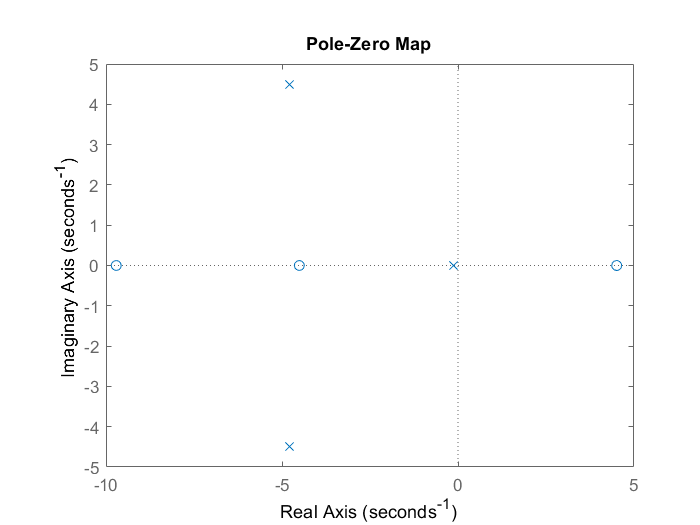


pzplot(transfer_matlab_form)